最近邻序列去噪算法效果

path = "D:\1-Codes\matlab\resource\dataset\N_MNIST_pic\N_MNIST_pic_train.mat"

path = "D:\1-Codes\matlab\resource\dataset\N_MNIST_pic\N_MNIST_pic_train.mat"

load(path)

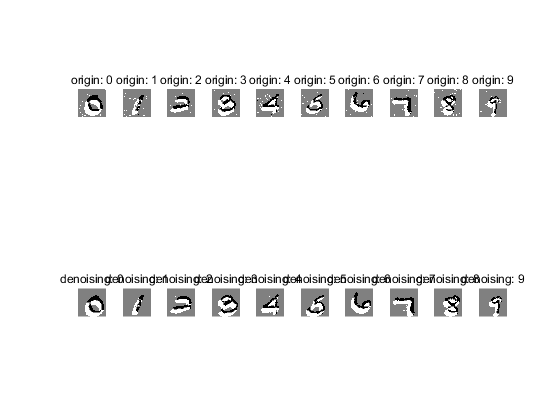

figure(1)
for i = 1:10
    pic = N_MNIST_pic_train((i-1)*6000+950,:,:);
    subplot(2,10,i)
    imshow(squeeze(pic),[])
    title(sprintf('origin: %d',i-1))    
    pic_gt = N_MNIST_pic_train_gt((i-1)*6000+950,:,:);
    subplot(2,10,i+10)
    imshow(squeeze(pic_gt),[])
    title(sprintf('denoising: %d',i-1))  
end